rng(12);  % Reproducibility

%% ================================================================
%%  LOCAL FUNCTIONS
%% ================================================================

% ----- Image Loading -----
function img = load_image_from_text(filename)
    fid = fopen(filename,'r');
    if fid == -1, error('Cannot open: %s', filename); end
    raw = fread(fid,'*char')';
    fclose(fid);
    raw(raw==char(10)|raw==char(13)) = [];
    img = reshape(raw(1:4096), 64, 64)';
    for i = 1:numel(img)
        c = img(i);
        if c>='0' && c<='9',       img(i) = c-'0';
        elseif c>='A' && c<='V',   img(i) = c-'A'+10;
        else,                       img(i) = 0;
        end
    end
    img = double(img);
end

% ----- Histogram -----
function [hv, hc] = calculate_histogram(img)
    hv = 0:31;  hc = zeros(1,32);
    vals = round(img(:));
    for v = vals'
        if v>=0 && v<=31, hc(v+1)=hc(v+1)+1; end
    end
end

% ----- Otsu Threshold -----
function thresh = otsu_threshold(img)
    [~,hc]  = calculate_histogram(img);
    p       = hc / sum(hc);
    thresh  = 0;  maxVar = 0;
    for t = 0:30
        w0 = sum(p(1:t+1));   w1 = sum(p(t+2:end));
        if w0==0 || w1==0, continue; end
        mu0 = sum((0:t)   .* p(1:t+1))   / w0;
        mu1 = sum((t+1:31).* p(t+2:end)) / w1;
        v   = w0*w1*(mu0-mu1)^2;
        if v > maxVar, maxVar=v; thresh=t+0.5; end
    end
end

% ----- Threshold Image -----
function bin = threshold_image(img, tval)
    if isempty(tval), tval = otsu_threshold(img); end
    bin = double(img >= tval);
end

% ----- Zhang-Suen Thinning -----
function out = thin_image(bin)
    img = bin;
    
    for iter = 1:500
        changed = false;
        for sub = 1:2
            [R,C] = size(img);
            mark  = false(R,C);
            for i = 2:R-1
                for j = 2:C-1
                    if img(i,j)==1 && zs_remove(img,i,j,sub)
                        mark(i,j) = true;
                    end
                end
            end
            if any(mark(:)), img(mark)=0; changed=true; end
        end
        if ~changed, break; end
    end
    out = img;
end

function tf = zs_remove(img,i,j,sub)
    p2=img(i-1,j); p3=img(i-1,j+1); p4=img(i,j+1);
    p5=img(i+1,j+1); p6=img(i+1,j); p7=img(i+1,j-1);
    p8=img(i,j-1);   p9=img(i-1,j-1);
    nb = [p2 p3 p4 p5 p6 p7 p8 p9];
    B  = sum(nb);
    if B<2||B>6, tf=false; return; end
    A  = 0;
    for k=1:8, if nb(k)==0&&nb(mod(k,8)+1)==1, A=A+1; end, end
    if A~=1, tf=false; return; end
    if sub==1
        if p2*p4*p6~=0||p4*p6*p8~=0, tf=false; return; end
    else
        if p2*p4*p8~=0||p2*p6*p8~=0, tf=false; return; end
    end
    tf = true;
end

% ----- Outline (erosion-based) -----
function out = detect_outline(bin)
    out = bin - erode_image(bin);
end

function er = erode_image(bin)
    [R,C] = size(bin);
    er = zeros(R,C);
    for i=2:R-1
        for j=2:C-1
            if all(all(bin(i-1:i+1,j-1:j+1)==1)), er(i,j)=1; end
        end
    end
end

% ----- Connected-Component Labelling -----
function [lbl, n] = label_objects(bin)
    [R,C] = size(bin);
    lbl   = zeros(R,C);
    n     = 0;
    for i=1:R
        for j=1:C
            if bin(i,j)==1 && lbl(i,j)==0
                n   = n+1;
                lbl = flood_fill(bin,lbl,i,j,n);
            end
        end
    end
end

function lbl = flood_fill(bin,lbl,r0,c0,lab)
    [R,C] = size(bin);
    stk   = [r0 c0];
    off   = [-1 -1;-1 0;-1 1;0 -1;0 1;1 -1;1 0;1 1];
    while ~isempty(stk)
        p=stk(end,:); stk(end,:)=[];
        r=p(1); c=p(2);
        if r<1||r>R||c<1||c>C||bin(r,c)==0||lbl(r,c)~=0, continue; end
        lbl(r,c) = lab;
        stk = [stk; r+off(:,1), c+off(:,2)]; %#ok<AGROW>
    end
end

% ----- Extract Character Crops -----
function [imgs, bbs] = extract_characters(lbl, n)
    imgs = cell(n,1);  bbs = zeros(n,4);
    for k=1:n
        [lr,lc] = find(lbl==k);
        if isempty(lr), continue; end
        r1=min(lr); r2=max(lr); c1=min(lc); c2=max(lc);
        bbs(k,:) = [r1 r2 c1 c2];
        crop = zeros(r2-r1+1, c2-c1+1);
        for i=1:length(lr), crop(lr(i)-r1+1,lc(i)-c1+1)=1; end
        imgs{k} = crop;
    end
end

% ----- Preprocess & Extract Features (pad→square, resize, flatten) -----
function feat = preprocess_and_extract(img, tsz)
    [h,w] = size(img);
    s  = max(h,w);
    sq = zeros(s,s);
    roff = floor((s-h)/2);  coff = floor((s-w)/2);
    sq(roff+1:roff+h, coff+1:coff+w) = img;
    rsz  = resize_nn(sq, tsz);
    feat = reshape(rsz,1,[]);
end

function out = resize_nn(img, tsz)
    [or,oc] = size(img);
    tr=tsz(1); tc=tsz(2);
    out = zeros(tr,tc);
    for i=1:tr
        for j=1:tc
            ri = max(1,min(round((i-0.5)*or/tr+0.5),or));
            ci = max(1,min(round((j-0.5)*oc/tc+0.5),oc));
            out(i,j) = img(ri,ci);
        end
    end
end

% ----- Arrange Characters in a Line -----
function arr = arrange_in_line(imgs, order, spacing)
    if nargin<3, spacing=10; end
    n   = length(order);
    mxh = 0;  tw = 0;
    for i=1:n
        ci=imgs{order(i)}; mxh=max(mxh,size(ci,1)); tw=tw+size(ci,2);
    end
    tw  = tw + spacing*(n-1);
    arr = zeros(mxh,tw);
    cc  = 1;
    for i=1:n
        ci = imgs{order(i)};  [h,w]=size(ci);
        roff = floor((mxh-h)/2);
        arr(roff+1:roff+h, cc:cc+w-1) = ci;
        cc = cc + w + spacing;
    end
end

% ----- Rotate Image (inverse mapping, nearest neighbour) -----
function out = rotate_image(img, deg)
    ang = -deg*pi/180;   % negative → counter-clockwise convention
    [R,C] = size(img);
    cr=R/2; cc=C/2;
    ca=cos(ang); sa=sin(ang);
    % New bounding box
    cor = [-cr -cc; -cr C-cc; R-cr -cc; R-cr C-cc];
    rc2 = cor(:,1)*ca - cor(:,2)*sa;
    cc2 = cor(:,1)*sa + cor(:,2)*ca;
    nh = ceil(max(rc2)-min(rc2));
    nw = ceil(max(cc2)-min(cc2));
    out = zeros(nh,nw);
    ncr=nh/2; ncc=nw/2;
    for i=1:nh
        for j=1:nw
            yn=i-ncr; xn=j-ncc;
            yo= yn*ca + xn*sa;
            xo=-yn*sa + xn*ca;
            ri=round(yo+cr); ci=round(xo+cc);
            if ri>=1&&ri<=R&&ci>=1&&ci<=C
                out(i,j)=img(ri,ci);
            end
        end
    end
end

% ----- KNN Classifier (custom, vectorised distances) -----
function pred = knn_classify(Xtr, Ytr, xq, k, verbose)
    if nargin<4, k=5; end
    dists = sqrt(sum((Xtr - xq).^2, 2));
    [~, idx] = sort(dists);
    kl    = Ytr(idx(1:k));
    votes = accumarray(kl, 1, [max(Ytr),1]);
    [~,pred] = max(votes);
    for i=1:verbose
        figure
        imshow(reshape(xq,[20,20]));
    end
end

% ----- SOM: Train -----
function [W, neuron_lbl] = train_som(X, Y, grid, epochs, init_lr)
    nr=grid(1); nc=grid(2);  NN=nr*nc;
    nf = size(X,2);  ns = size(X,1);
    ncls = max(Y);
    init_radius = max(grid)/2;

    % Initialise weights from random training samples
    ri = randperm(ns, min(NN,ns));
    W  = zeros(NN,nf);
    W(1:length(ri),:) = X(ri,:);
    if length(ri)<NN
        W(length(ri)+1:end,:) = X(randi(ns,NN-length(ri),1),:);
    end

    % Neuron grid positions
    [gc,gr] = meshgrid(1:nc,1:nr);
    NP = [gr(:), gc(:)];   % NN×2

    for ep = 1:epochs
        lr  = init_lr  * exp(-ep/epochs*3);
        rad = max(0.5,  init_radius * exp(-ep/epochs*3));
        r2  = 2*rad^2;
        perm = randperm(ns);
        for s = 1:ns
            x   = X(perm(s),:);
            d   = sum((W-x).^2, 2);
            [~,bmu] = min(d);
            nd  = sum((NP-NP(bmu,:)).^2, 2);
            h   = exp(-nd/r2);         % NN×1
            W   = W + lr * h .* (x-W);% broadcast
        end
        if mod(ep,50)==0
            fprintf('    SOM epoch %d/%d\n', ep, epochs);
        end
    end

    % Label neurons by majority vote
    votes = zeros(NN, ncls);
    for s = 1:ns
        d = sum((W-X(s,:)).^2, 2);
        [~,bmu] = min(d);
        votes(bmu, Y(s)) = votes(bmu, Y(s)) + 1;
    end
    neuron_lbl = ones(NN,1);
    for n=1:NN
        if any(votes(n,:)>0), [~,neuron_lbl(n)]=max(votes(n,:)); end
    end
end

% ----- SOM: Classify -----
function pred = som_classify(xq, W, neuron_lbl)
    d = sum((W-xq).^2, 2);
    [~,bmu] = min(d);
    pred = neuron_lbl(bmu);
end

% ----- Confusion Matrix + Plot -----
function CM = compute_cm(Yt, Yp, nc)
    CM = zeros(nc,nc);
    for i=1:length(Yt)
        if Yt(i)>=1&&Yt(i)<=nc&&Yp(i)>=1&&Yp(i)<=nc
            CM(Yt(i),Yp(i)) = CM(Yt(i),Yp(i))+1;
        end
    end
end

function plot_confusion_matrix(Yt, Yp, cnames, ttl)
    nc = length(cnames);
    CM = compute_cm(Yt, Yp, nc);
    figure('Name', ttl);
    imagesc(CM); colormap(hot); colorbar;
    title(ttl);
    xlabel('Predicted'); ylabel('True');
    xticks(1:nc); yticks(1:nc);
    xticklabels(cnames); yticklabels(cnames);
    for i=1:nc
        for j=1:nc
            if CM(i,j)>0
                text(j,i,num2str(CM(i,j)),'HorizontalAlignment','center',...
                    'Color','white','FontWeight','bold','FontSize',9);
            end
        end
    end
end


%% ================================================================
%% SECTION 1 – LOAD & DISPLAY ORIGINAL IMAGES
%% ================================================================
fprintf('=== Loading Images ===\n');

=== Loading Images ===


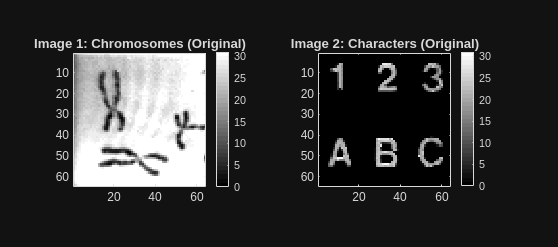

img1_original = load_image_from_text('chromo.txt');
img2_original = load_image_from_text('charact1.txt');

figure('Name','[Task 1] Original Images','Position',[50 50 950 420]);
subplot(1,2,1); imagesc(img1_original); colormap(gray(32)); colorbar;
title('Image 1: Chromosomes (Original)'); axis equal tight;
subplot(1,2,2); imagesc(img2_original); colormap(gray(32)); colorbar;
title('Image 2: Characters (Original)'); axis equal tight;

%% ================================================================
%% SECTION 2 – IMAGE 1: CHROMOSOMES
%% ================================================================
fprintf('\n=== Image 1: Chromosomes ===\n');


=== Image 1: Chromosomes ===


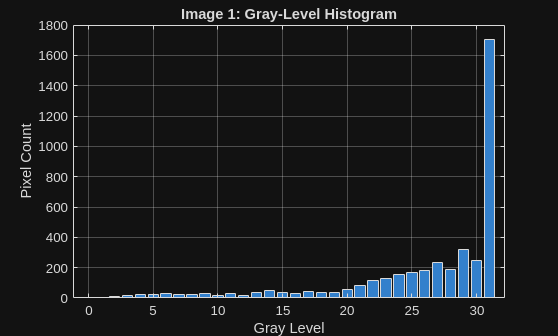


% --- Histogram (custom) ---
[hv, hc] = calculate_histogram(img1_original);
figure('Name','[Image 1] Histogram');
bar(hv, hc, 'FaceColor',[0.2 0.5 0.8]);
xlabel('Gray Level'); ylabel('Pixel Count');
title('Image 1: Gray-Level Histogram'); grid on;

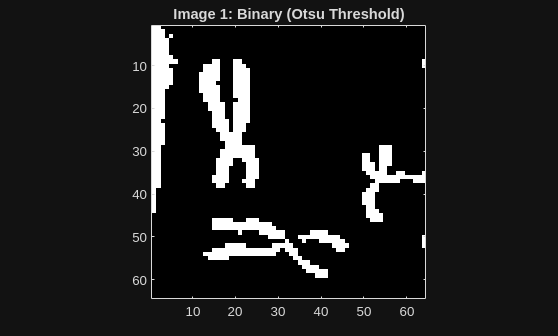


% --- Task 2: Threshold ---
% Chromosomes are DARK on LIGHT background → invert before thresholding
img1_inv = max(img1_original(:)) - img1_original;
img1_binary = threshold_image(img1_inv, []);
% Safety: ensure foreground (chromosomes) = 1
if mean(img1_binary(:)) > 0.5, img1_binary = 1 - img1_binary; end

figure('Name','[Image 1] Binary');
imagesc(img1_binary); colormap(gray);
title('Image 1: Binary (Otsu Threshold)'); axis equal tight;


% --- Task 3: Thinning (Zhang-Suen) ---
fprintf('  Thinning Image 1 (Zhang-Suen) ...\n');

  Thinning Image 1 (Zhang-Suen) ...


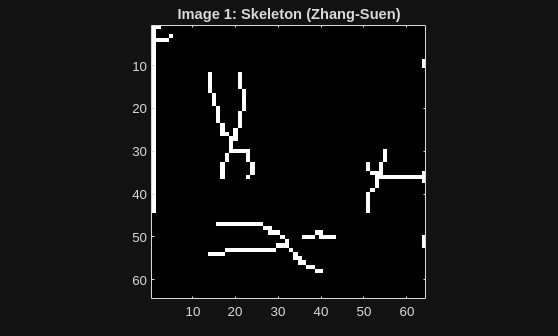

img1_thinned = thin_image(img1_binary);
figure('Name','[Image 1] Thinned');
imagesc(img1_thinned); colormap(gray);
title('Image 1: Skeleton (Zhang-Suen)'); axis equal tight;

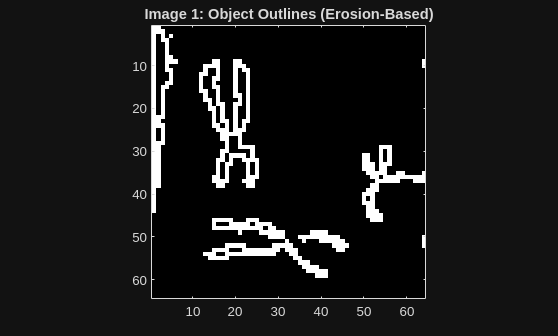


% --- Task 4: Outline ---
img1_outline = detect_outline(img1_binary);
figure('Name','[Image 1] Outline');
imagesc(img1_outline); colormap(gray);
title('Image 1: Object Outlines (Erosion-Based)'); axis equal tight;


% --- Task 5: Label Objects ---
[img1_labeled, n_chromo] = label_objects(img1_binary);
fprintf('  Image 1: %d chromosome(s) detected\n', n_chromo);

  Image 1: 7 chromosome(s) detected


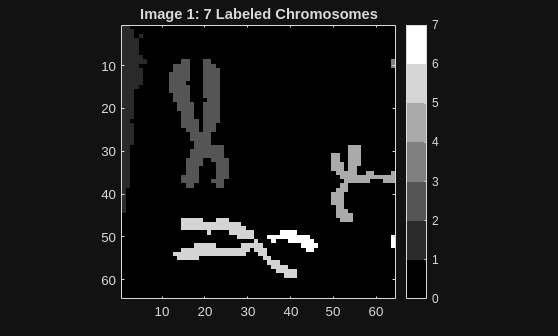

figure('Name','[Image 1] Labeled');
imagesc(img1_labeled); colormap(colorcube(max(n_chromo,2))); colorbar;
title(sprintf('Image 1: %d Labeled Chromosomes', n_chromo)); axis equal tight;

%% ================================================================
%% SECTION 3 – IMAGE 2: CHARACTERS (Tasks 1-5)
%% ================================================================
fprintf('\n=== Image 2: Characters ===\n');


=== Image 2: Characters ===


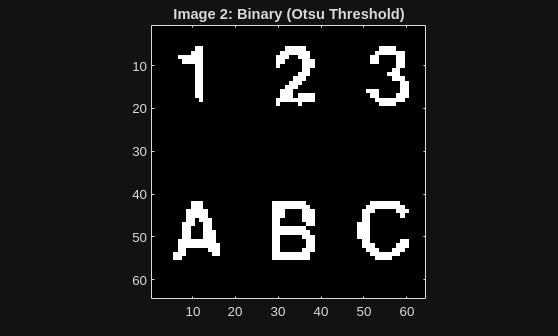


% --- Task 2: Threshold ---
img2_binary = threshold_image(img2_original, []);
if mean(img2_binary(:)) > 0.5, img2_binary = 1 - img2_binary; end
figure('Name','[Image 2] Binary');
imagesc(img2_binary); colormap(gray);
title('Image 2: Binary (Otsu Threshold)'); axis equal tight;


% --- Task 3: Thinning ---
fprintf('  Thinning Image 2 (Zhang-Suen) ...\n');

  Thinning Image 2 (Zhang-Suen) ...


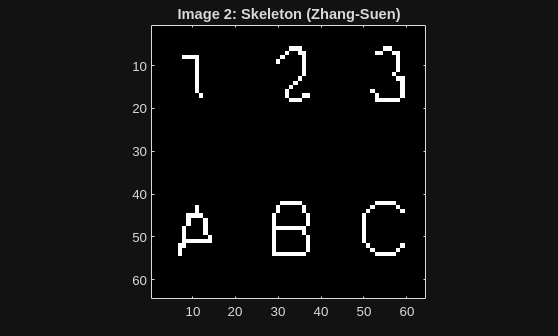

img2_thinned = thin_image(img2_binary);
figure('Name','[Image 2] Thinned');
imagesc(img2_thinned); colormap(gray);
title('Image 2: Skeleton (Zhang-Suen)'); axis equal tight;

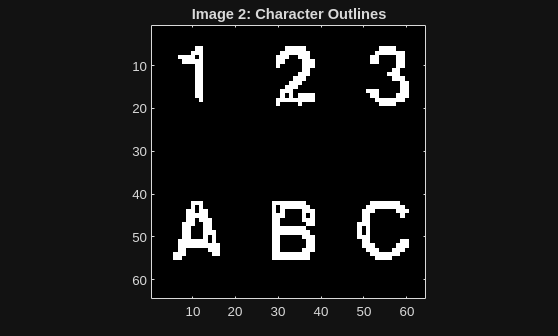


% --- Task 4: Outline ---
img2_outline = detect_outline(img2_binary);
figure('Name','[Image 2] Outline');
imagesc(img2_outline); colormap(gray);
title('Image 2: Character Outlines'); axis equal tight;


% --- Task 5: Segment & Label ---
[img2_labeled, num_chars] = label_objects(img2_binary);
fprintf('  Image 2: %d character(s) found\n', num_chars);

  Image 2: 6 character(s) found


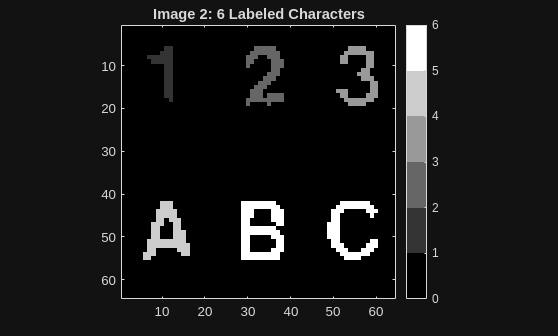

figure('Name','[Image 2] Labeled');
imagesc(img2_labeled); colormap(colorcube(max(num_chars,2))); colorbar;
title(sprintf('Image 2: %d Labeled Characters', num_chars)); axis equal tight;

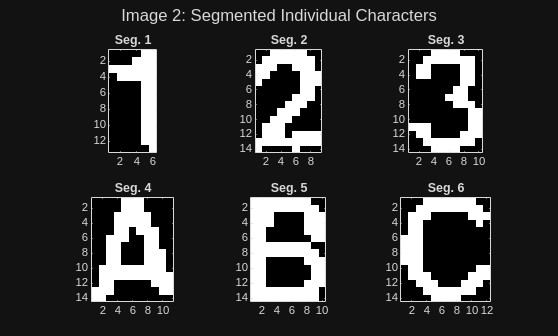


% Extract bounding-box crops for each character
[char_images, char_bboxes] = extract_characters(img2_labeled, num_chars);

figure('Name','[Image 2] Extracted Characters');
for i = 1:min(num_chars, 6)
    subplot(2,3,i); imagesc(char_images{i}); colormap(gray);
    title(sprintf('Seg. %d',i)); axis equal tight;
end
sgtitle('Image 2: Segmented Individual Characters');

%% ================================================================
%% SECTION 4 – LOAD TRAINING DATASET (p_dataset_26)
%% ================================================================
fprintf('\n=== Loading Training Dataset ===\n');


=== Loading Training Dataset ===



% Folder → numeric label (1-6) → character name
% Sample1 → '1', Sample2 → '2', Sample3 → '3',
% SampleA → 'A', SampleB → 'B', SampleC → 'C'
CLASS_CFG = {
    'Sample1', 1, '1';
    'Sample2', 2, '2';
    'Sample3', 3, '3';
    'SampleA', 4, 'A';
    'SampleB', 5, 'B';
    'SampleC', 6, 'C'};
N_CLASSES   = size(CLASS_CFG,1);
CLASS_NAMES = CLASS_CFG(:,3);          % {'1','2','3','A','B','C'}
DATASET_DIR = 'p_dataset_26';
TARGET_SIZE = [20, 20];                % Feature image size
N_FEAT      = prod(TARGET_SIZE);

all_X = []; all_Y = [];

for c = 1:N_CLASSES
    folder = fullfile(DATASET_DIR, CLASS_CFG{c,1});
    if ~exist(folder,'dir')
        fprintf('  WARNING: folder not found – %s\n', folder); continue;
    end
    mats = dir(fullfile(folder,'*.mat'));
    cnt  = 0;
    for f = 1:length(mats)
        try
            S   = load(fullfile(folder, mats(f).name));
            fn  = fieldnames(S);
            img = double(S.(fn{1}));
            if max(img(:)) > 1, img = img / max(img(:)); end
            img = double(img >= 0.5);
            % Correct polarity: character pixels = 1 (minority)
            if mean(img(:)) > 0.5, img = 1 - img; end
            feat    = preprocess_and_extract(img, TARGET_SIZE);
            all_X   = [all_X; feat];        %#ok<AGROW>
            all_Y   = [all_Y; c];           %#ok<AGROW>
            cnt = cnt + 1;
        catch, end
    end
    fprintf('  Class %-3s : %d samples\n', CLASS_CFG{c,3}, cnt);
end

  Class 1   : 1016 samples
  Class 2   : 1016 samples
  Class 3   : 1016 samples
  Class A   : 1016 samples
  Class B   : 1016 samples
  Class C   : 1016 samples


fprintf('  Total loaded: %d samples\n', size(all_X,1));

  Total loaded: 6096 samples



% 75 / 25 stratified random split
perm   = randperm(size(all_X,1));
sp     = floor(0.75 * size(all_X,1));
train_X = all_X(perm(1:sp),     :);  train_Y = all_Y(perm(1:sp));
test_X  = all_X(perm(sp+1:end), :);  test_Y  = all_Y(perm(sp+1:end));
fprintf('  Train: %d   Test: %d\n', length(train_Y), length(test_Y));

  Train: 4572   Test: 1524


%% ================================================================
%% SECTION 5 – HYPERPARAMETER SWEEP: FEATURE SIZE  (Task 9)
%% ================================================================
fprintf('\n=== Hyperparameter Sweep: Feature Size (kNN k=5) ===\n');


=== Hyperparameter Sweep: Feature Size (kNN k=5) ===


feat_sizes  = {[10,10],[16,16],[20,20],[28,28]};
feat_labels = {'10x10','16x16','20x20','28x28'};
size_accs   = zeros(1,4);

for si = 1:4
    fs   = feat_sizes{si};
    % Re-extract features at this size (from the already-loaded 20x20 arrays
    % by re-loading originals is safest; here we reshape 20x20 → orig → new)
    Xtr2 = zeros(length(train_Y), prod(fs));
    Xte2 = zeros(length(test_Y),  prod(fs));
    for i = 1:length(train_Y)
        img20 = reshape(train_X(i,:), TARGET_SIZE);
        Xtr2(i,:) = preprocess_and_extract(img20, fs);
    end
    for i = 1:length(test_Y)
        img20 = reshape(test_X(i,:), TARGET_SIZE);
        Xte2(i,:) = preprocess_and_extract(img20, fs);
    end
    correct = 0;
    for i = 1:size(Xte2,1)
        p = knn_classify(Xtr2, train_Y, Xte2(i,:), 5,0);
        correct = correct + (p == test_Y(i));
    end
    size_accs(si) = 100*correct/size(Xte2,1);
    fprintf('  %s → %.2f%%\n', feat_labels{si}, size_accs(si));
end

  10x10 → 94.16%
  16x16 → 95.41%
  20x20 → 95.73%
  28x28 → 95.60%


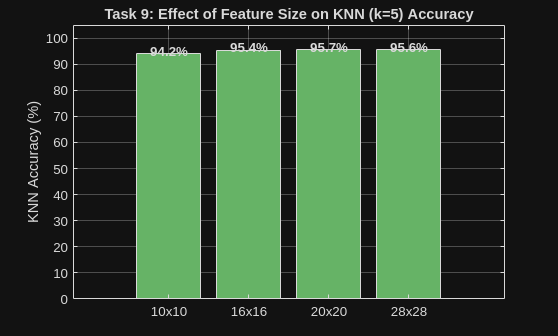


figure('Name','[Hyperparam] Feature Size');
bar(size_accs,'FaceColor',[0.4 0.7 0.4]);
xticklabels(feat_labels); ylabel('KNN Accuracy (%)');
title('Task 9: Effect of Feature Size on KNN (k=5) Accuracy');
ylim([0 105]); grid on;
for i=1:4, text(i,size_accs(i)+1,sprintf('%.1f%%',size_accs(i)),...
        'HorizontalAlignment','center','FontWeight','bold'); end

%% ================================================================
%% SECTION 6 – CLASSIFIER 1: K-NEAREST NEIGHBOURS  (Task 8)
%% ================================================================
fprintf('\n=== KNN Classifier ===\n');


=== KNN Classifier ===


k_vals    = [1,3,5,7,9,11];
knn_accs  = zeros(1,length(k_vals));

for ki = 1:length(k_vals)
    correct = 0;
    for i = 1:size(test_X,1)
        p = knn_classify(train_X, train_Y, test_X(i,:), k_vals(ki),0);
        correct = correct + (p == test_Y(i));
    end
    knn_accs(ki) = 100*correct/size(test_X,1);
    fprintf('  k = %2d → %.2f%%\n', k_vals(ki), knn_accs(ki));
end

  k =  1 → 97.57%
  k =  3 → 96.13%
  k =  5 → 95.73%
  k =  7 → 95.87%
  k =  9 → 94.82%
  k = 11 → 94.82%



[best_knn_acc, best_ki] = max(knn_accs);
best_k = k_vals(best_ki);
fprintf('  Best KNN: k=%d → %.2f%%\n', best_k, best_knn_acc);

  Best KNN: k=1 → 97.57%


ans = 4

ans = 1

ans = 6

ans = 4

ans = 3

ans = 5

ans = 5

ans = 1

ans = 1

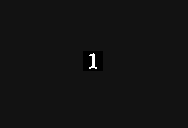

ans = 1

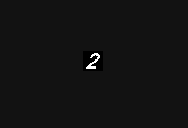

ans = 2

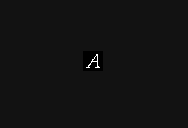

ans = 4

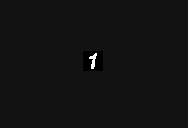

ans = 1

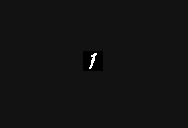

ans = 1

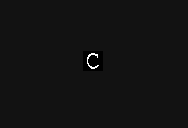

ans = 6


% k-tuning curve
figure('Name','[KNN] k Tuning');
plot(k_vals, knn_accs,'b-o','LineWidth',2,'MarkerSize',8);
xlabel('k'); ylabel('Test Accuracy (%)');
title(sprintf('KNN: k-Tuning (Best k=%d → %.1f%%)',best_k,best_knn_acc));
xticks(k_vals); grid on;

% Final predictions with best k
knn_preds = zeros(size(test_Y));
for i = 1:size(test_X,1)
    if mod(i,100)==0
        knn_preds(i) = knn_classify(train_X, train_Y, test_X(i,:), best_k,1);
        knn_preds(i)
    else
        knn_preds(i) = knn_classify(train_X, train_Y, test_X(i,:), best_k,0);
    end
end

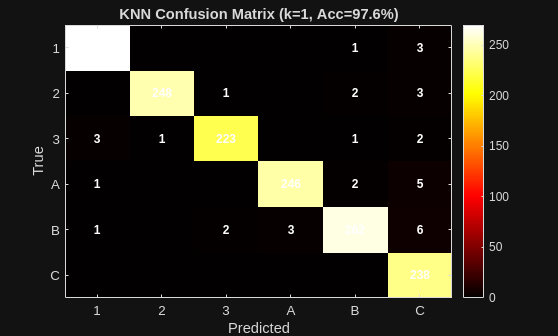

plot_confusion_matrix(test_Y, knn_preds, CLASS_NAMES, ...
    sprintf('KNN Confusion Matrix (k=%d, Acc=%.1f%%)', best_k, best_knn_acc));

%% ================================================================
%% SECTION 7 – CLASSIFIER 2: SUPPORT VECTOR MACHINE  (Task 8)
%% ================================================================
fprintf('\n=== SVM Classifier (fitcecoc – Statistics Toolbox) ===\n');


=== SVM Classifier (fitcecoc – Statistics Toolbox) ===


svm_kernels   = {'linear','gaussian','polynomial'};
svm_accs      = zeros(1,length(svm_kernels));
svm_mdls      = cell(1,length(svm_kernels));

for ki = 1:length(svm_kernels)
    fprintf('  Training SVM (%s) ...\n', svm_kernels{ki});
    try
        if strcmp(svm_kernels{ki},'polynomial')
            t = templateSVM('KernelFunction','polynomial','PolynomialOrder',2,...
                'Standardize',true,'BoxConstraint',1);
        else
            t = templateSVM('KernelFunction',svm_kernels{ki},...
                'Standardize',true,'BoxConstraint',100);
        end
        mdl = fitcecoc(train_X, train_Y, 'Learners', t, 'Coding','onevsone');
        preds = predict(mdl, test_X);
        svm_accs(ki) = 100 * sum(preds==test_Y) / length(test_Y);
        svm_mdls{ki} = mdl;
        fprintf('    → %.2f%%\n', svm_accs(ki));
    catch e
        fprintf('    FAILED: %s\n', e.message);
        svm_accs(ki) = 0;
    end
end

  Training SVM (linear) ...


    → 95.28%


  Training SVM (gaussian) ...


    → 38.78%


  Training SVM (polynomial) ...


    → 95.54%



% Kernel comparison chart
figure('Name','[SVM] Kernel Comparison');
bar(svm_accs,'FaceColor',[0.8 0.3 0.3]);
xticklabels(svm_kernels); ylabel('Test Accuracy (%)');
title('SVM: Kernel Comparison'); ylim([0 105]); grid on;
for i=1:length(svm_kernels), text(i,svm_accs(i)+1,sprintf('%.1f%%',svm_accs(i)),...
        'HorizontalAlignment','center','FontWeight','bold'); end

[best_svm_acc, best_svm_ki] = max(svm_accs);
best_svm_mdl  = svm_mdls{best_svm_ki};
svm_preds_all = predict(best_svm_mdl, test_X);
fprintf('  Best SVM: %s → %.2f%%\n', svm_kernels{best_svm_ki}, best_svm_acc);

  Best SVM: polynomial → 95.54%



plot_confusion_matrix(test_Y, svm_preds_all, CLASS_NAMES, ...
    sprintf('SVM Confusion Matrix (%s, Acc=%.1f%%)', ...
    svm_kernels{best_svm_ki}, best_svm_acc));


% --- Box constraint (C) hyperparameter sweep for best kernel ---
fprintf('\n  SVM Box-Constraint (C) sweep for %s kernel:\n', svm_kernels{best_svm_ki});


  SVM Box-Constraint (C) sweep for polynomial kernel:


C_vals   = [0.01,0.1, 1, 10, 100];
C_accs   = zeros(1,length(C_vals));
for ci = 1:length(C_vals)
    try
        if strcomp(svm_kernels{best_svm_ki},'polynomial')
            templateSVM('KernelFunction','polynomial','PolynomialOrder',2,...
                'Standardize',true,'BoxConstraint',C_vals(ci));
        else
            t2   = templateSVM('KernelFunction',svm_kernels{best_svm_ki},...
                    'Standardize',true,'BoxConstraint',C_vals(ci));
        end
        mdl2 = fitcecoc(train_X, train_Y,'Learners',t2,'Coding','onevsone');
        p2   = predict(mdl2, test_X);
        C_accs(ci) = 100*sum(p2==test_Y)/length(test_Y);
    catch, C_accs(ci)=0; end
    fprintf('    C=%-5g → %.2f%%\n', C_vals(ci), C_accs(ci));
end

    C=0.01  → 0.00%
    C=0.1   → 0.00%
    C=1     → 0.00%
    C=10    → 0.00%
    C=100   → 0.00%


figure('Name','[SVM] C Hyperparameter');
semilogx(C_vals, C_accs,'r-s','LineWidth',2,'MarkerSize',8);
xlabel('Box Constraint C'); ylabel('Test Accuracy (%)');
title(sprintf('SVM (%s): Effect of C',svm_kernels{best_svm_ki})); grid on;

%% ================================================================
%% SECTION 8 – CLASSIFIER 3: SELF-ORGANISING MAP  (Task 8)
%% ================================================================
fprintf('\n=== SOM Classifier ===\n');


=== SOM Classifier ===


som_grids      = {[8,8],[10,10],[26,26],[32,32]};
som_grid_strs  = {'8x8','10x10','26x26','32x32'};
som_grid_accs  = zeros(1,4);

for gi = 1:4
    fprintf('  Training SOM %s ...\n', som_grid_strs{gi});
    [sw, sl] = train_som(train_X, train_Y, som_grids{gi}, 100, 0.5);
    correct  = 0;
    for i = 1:size(test_X,1)
        p = som_classify(test_X(i,:), sw, sl);
        correct = correct + (p == test_Y(i));
    end
    som_grid_accs(gi) = 100*correct/size(test_X,1);
    fprintf('    → %.2f%%\n', som_grid_accs(gi));
end

  Training SOM 8x8 ...


    SOM epoch 50/100
    SOM epoch 100/100


    → 87.47%


  Training SOM 10x10 ...


    SOM epoch 50/100
    SOM epoch 100/100


    → 89.04%


  Training SOM 26x26 ...


    SOM epoch 50/100
    SOM epoch 100/100


    → 91.60%


  Training SOM 32x32 ...


    SOM epoch 50/100
    SOM epoch 100/100


    → 90.62%


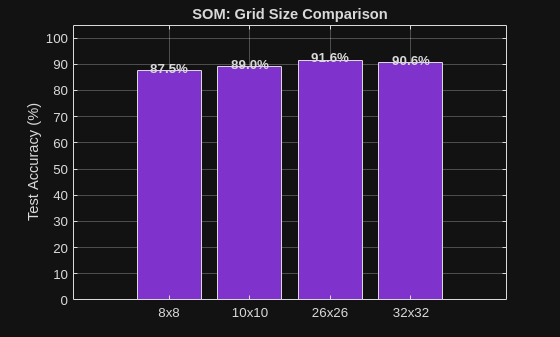


figure('Name','[SOM] Grid-Size Comparison');
bar(som_grid_accs,'FaceColor',[0.5 0.2 0.8]);
xticklabels(som_grid_strs); ylabel('Test Accuracy (%)');
title('SOM: Grid Size Comparison'); ylim([0 105]); grid on;
for i=1:4, text(i,som_grid_accs(i)+1,sprintf('%.1f%%',som_grid_accs(i)),...
        'HorizontalAlignment','center','FontWeight','bold'); end


[best_som_acc, best_som_gi] = max(som_grid_accs);
fprintf('  Best SOM grid: %s → %.2f%%\n', som_grid_strs{best_som_gi}, best_som_acc);

  Best SOM grid: 26x26 → 91.60%



fprintf('  Re-training best SOM with 200 epochs ...\n');

  Re-training best SOM with 200 epochs ...


[best_sw, best_sl] = train_som(train_X, train_Y, som_grids{best_som_gi}, 250, 0.5);

    SOM epoch 50/250
    SOM epoch 100/250
    SOM epoch 150/250
    SOM epoch 200/250
    SOM epoch 250/250


som_preds_all = zeros(size(test_Y));
for i = 1:size(test_X,1)
    som_preds_all(i) = som_classify(test_X(i,:), best_sw, best_sl);
end
best_som_acc_final = 100*sum(som_preds_all==test_Y)/length(test_Y);
fprintf('  Final SOM accuracy: %.2f%%\n', best_som_acc_final);

  Final SOM accuracy: 91.27%


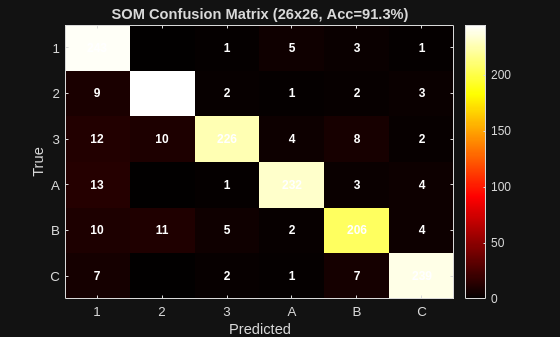


plot_confusion_matrix(test_Y, som_preds_all, CLASS_NAMES, ...
    sprintf('SOM Confusion Matrix (%s, Acc=%.1f%%)', ...
    som_grid_strs{best_som_gi}, best_som_acc_final));

%% ================================================================
%% SECTION 9 – CLASSIFIER COMPARISON & BEST MODEL SELECTION
%% ================================================================
fprintf('\n=== Classifier Comparison ===\n');


=== Classifier Comparison ===


all_accs  = [best_knn_acc, best_svm_acc, best_som_acc_final];

Unrecognized function or variable 'best_som_acc_final'.

all_names = {sprintf('KNN(k=%d)',best_k), ...
             sprintf('SVM(%s)',svm_kernels{best_svm_ki}), ...
             sprintf('SOM(%s)',som_grid_strs{best_som_gi})};

for i=1:3, fprintf('  %-22s %.2f%%\n', all_names{i}, all_accs(i)); end

figure('Name','[Summary] Classifier Comparison');
b = bar(all_accs,'FaceColor','flat');
b.CData = [0.2 0.5 0.8; 0.8 0.3 0.3; 0.5 0.2 0.8];
xticklabels(all_names); ylabel('Test Accuracy (%)');
title('Classifier Performance Comparison (Test Set)');
ylim([0 110]); grid on;
for i=1:3, text(i, all_accs(i)+1, sprintf('%.1f%%',all_accs(i)),...
        'HorizontalAlignment','center','FontWeight','bold','FontSize',11); end

[~, best_model_idx] = max(all_accs);
fprintf('\nSelected Best Model: %s (%.2f%%)\n', ...
        all_names{best_model_idx}, all_accs(best_model_idx));

%% ================================================================
%% SECTION 10 – CLASSIFY CHARACTERS IN IMAGE 2  (Task 8)
%% ================================================================
fprintf('\n=== Classifying Characters in Image 2 ===\n');


=== Classifying Characters in Image 2 ===



img2_feat = zeros(num_chars, N_FEAT);
for i = 1:num_chars
    img2_feat(i,:) = preprocess_and_extract(char_images{i}, TARGET_SIZE);
end

% Run all three classifiers on Image 2
img2_knn_pred = zeros(num_chars,1);
img2_svm_pred = zeros(num_chars,1);
img2_som_pred = zeros(num_chars,1);

for i = 1:num_chars
    img2_knn_pred(i) = knn_classify(train_X, train_Y, img2_feat(i,:), best_k,0);
    img2_svm_pred(i) = predict(best_svm_mdl, img2_feat(i,:));
    img2_som_pred(i) = som_classify(img2_feat(i,:), best_sw, best_sl);
end

% Pick final prediction from best model
switch best_model_idx
    case 1, img2_final = img2_knn_pred;
    case 2, img2_final = img2_svm_pred;
    case 3, img2_final = img2_som_pred;
end

fprintf('\n  Char | KNN  | SVM  | SOM  | BEST (%s)\n', all_names{best_model_idx});


  Char | KNN  | SVM  | SOM  | BEST (KNN(k=1))


fprintf('  -----|------|------|------|----------\n');

  -----|------|------|------|----------


for i = 1:num_chars
    fprintf('  %4d | %-4s | %-4s | %-4s | %s\n', i, ...
        CLASS_NAMES{img2_knn_pred(i)}, CLASS_NAMES{img2_svm_pred(i)}, ...
        CLASS_NAMES{img2_som_pred(i)}, CLASS_NAMES{img2_final(i)});
end

     1 | 1    | 1    | 1    | 1
     2 | 2    | 2    | 2    | 2
     3 | B    | 2    | B    | B
     4 | A    | A    | A    | A
     5 | B    | B    | B    | B
     6 | C    | C    | C    | C


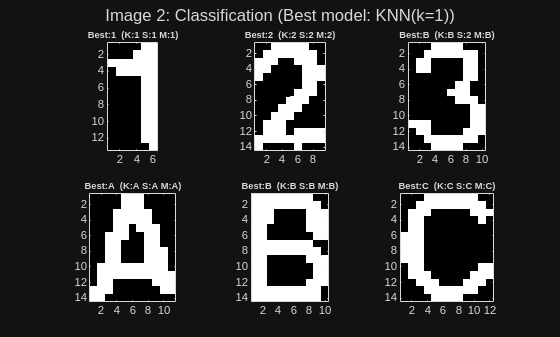


% Display with predicted labels
figure('Name','[Image 2] Classification Results');
for i = 1:min(num_chars,6)
    subplot(2,3,i); imagesc(char_images{i}); colormap(gray);
    title(sprintf('Best:%s  (K:%s S:%s M:%s)', ...
        CLASS_NAMES{img2_final(i)}, CLASS_NAMES{img2_knn_pred(i)}, ...
        CLASS_NAMES{img2_svm_pred(i)}, CLASS_NAMES{img2_som_pred(i)}), ...
        'FontSize',7);
    axis equal tight;
end
sgtitle(sprintf('Image 2: Classification (Best model: %s)', all_names{best_model_idx}));

%% ================================================================
%% SECTION 11 – TASK 6: ARRANGE AS AB123C (using classifier output)
%% ================================================================
fprintf('\n=== Task 6: Arrange Characters as A B 1 2 3 C ===\n');


=== Task 6: Arrange Characters as A B 1 2 3 C ===



TARGET_SEQ  = {'A','B','1','2','3','C'};
order_idxs  = zeros(1,6);
used_flags  = false(num_chars,1);

for t = 1:6
    for i = 1:num_chars
        if ~used_flags(i) && strcmp(CLASS_NAMES{img2_final(i)}, TARGET_SEQ{t})
            order_idxs(t) = i;
            used_flags(i) = true;
            break;
        end
    end
    if order_idxs(t)==0
        warning('Character "%s" not identified in Image 2!', TARGET_SEQ{t});
    end
end

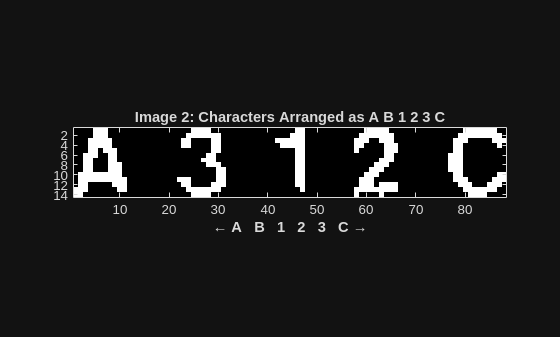


valid_order  = order_idxs(order_idxs > 0);
img2_arranged = arrange_in_line(char_images, valid_order, 10);

figure('Name','[Image 2] Arranged AB123C');
imagesc(img2_arranged); colormap(gray);
title('Image 2: Characters Arranged as A B 1 2 3 C');
axis equal tight;
xlabel('← A   B   1   2   3   C →','FontSize',11,'FontWeight','bold');

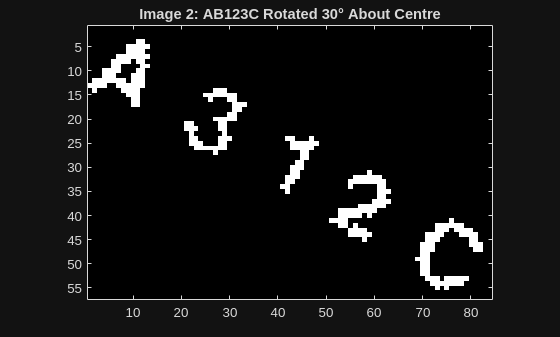

%% ================================================================
%% SECTION 12 – TASK 7: ROTATE 30 DEGREES ABOUT CENTRE
%% ================================================================
img2_rotated = rotate_image(img2_arranged, 30);

figure('Name','[Image 2] Rotated 30 Degrees');
imagesc(img2_rotated); colormap(gray);
title('Image 2: AB123C Rotated 30° About Centre');
axis equal tight;


fprintf('\n=== ALL TASKS COMPLETE ===\n');


=== ALL TASKS COMPLETE ===
